For 1-radian step reference design criteria

- Settling time<0.04 sec

- Overshoot < 16%

- No steady state error,even in the presence of step disturbance

j=3.2284E-6

J = 3.2284e-06

B=3.5077*10^-6

b = 3.5077e-06

k=0.0274

K = 0.0274

r=4

R = 4

l=2.75*10^-6

L = 2.7500e-06

s=tf('s');
P_Motor=k/(s*((j*s+B)*(l*s+r)+k^2))

P_Motor =
 
                    0.0274
  -------------------------------------------
  8.878e-12 s^3 + 1.291e-05 s^2 + 0.0007648 s
 
Continuous-time transfer function.



PID TF= Kp + Kd*s + Ki/s = (kd*s^2+kp*s+ki)/s

1.Proportional control

kp=1;
for i=1:3
    c(:,:,i)= pid(kp);
    kp =kp+10;
end
sys_cl=feedback(c*P_Motor,1);

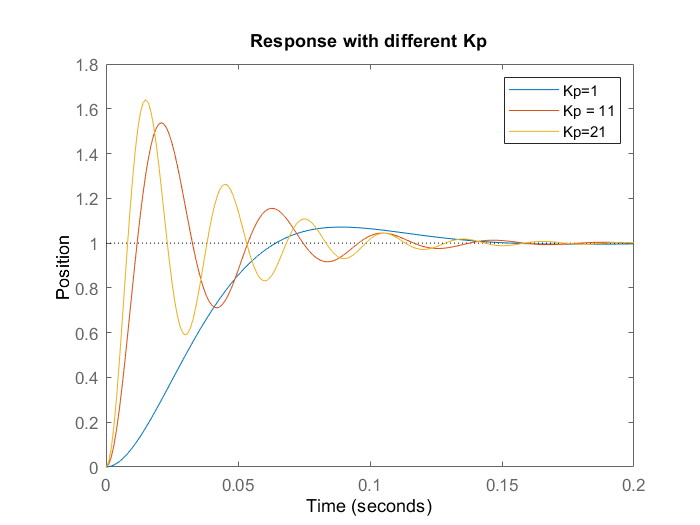

t=0:0.001:0.2;
step(sys_cl(:,:,1),sys_cl(:,:,2),sys_cl(:,:,3),t)
ylabel('Position')
title('Response with different Kp')
legend('Kp=1','Kp = 11','Kp=21')

considering controller in feedback path for no steady state error

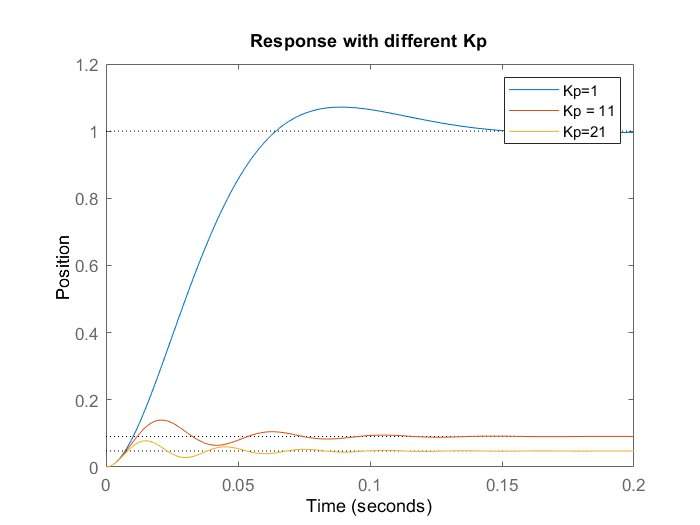

dist_cl=feedback(P_Motor,c);
step(dist_cl(:,:,1),dist_cl(:,:,2),dist_cl(:,:,3),t)
ylabel('Position')
title('Response with different Kp')
legend('Kp=1','Kp = 11','Kp=21')

graph shows no steady state error for Kp=21 because it reaches to steady state quickly

PI Control

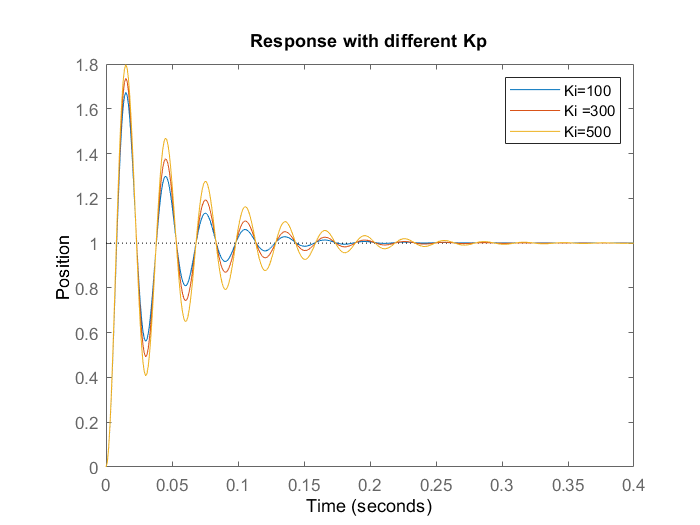

kp=21;
ki=100;
for i=1:5
    c(:,:,i)=pid(kp,ki);
    ki=ki+200;
end
sys_cl=feedback(c*P_Motor,1);
t=0:0.001:0.4;
step(sys_cl(:,:,1),sys_cl(:,:,2),sys_cl(:,:,3),t)
ylabel('Position')
title('Response with different Kp')
legend('Ki=100','Ki =300','Ki=500')

Taking controller in feedback

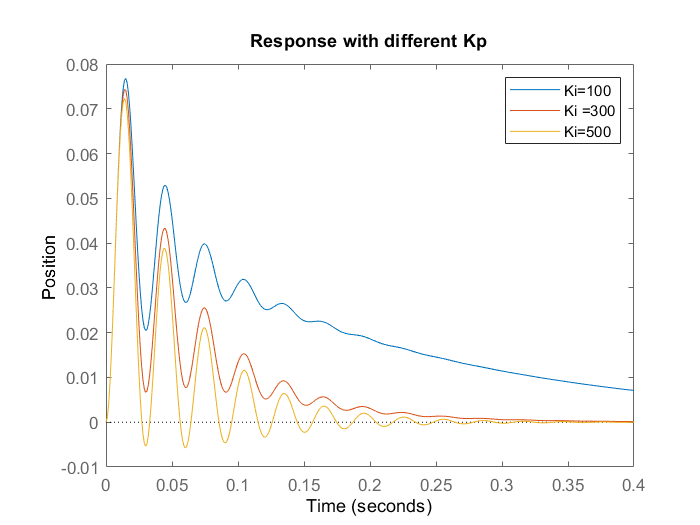

dist_cl=feedback(P_Motor,c);
t=0:0.001:0.4;
step(dist_cl(:,:,1),dist_cl(:,:,2),dist_cl(:,:,3),t)
ylabel('Position')
title('Response with different Kp')
legend('Ki=100','Ki =300','Ki=500')

At Ki=500 it reaches to zero quickly

PID Controller

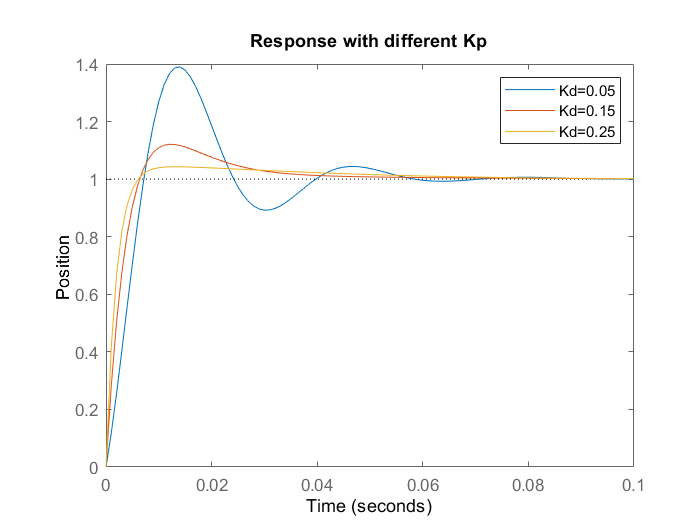

kp=21;
ki=500;
kd=0.05;
 for i=1:3
     c(:,:,i)=pid(kp,ki,kd);
     kd=kd+0.1;
 end
 
sys_cl=feedback(c*P_Motor,1);
t=0:0.001:0.1;
step(sys_cl(:,:,1),sys_cl(:,:,2),sys_cl(:,:,3),t)
ylabel('Position')
title('Response with different Kp')
legend('Kd=0.05','Kd=0.15','Kd=0.25')

 Taking controller in feedback

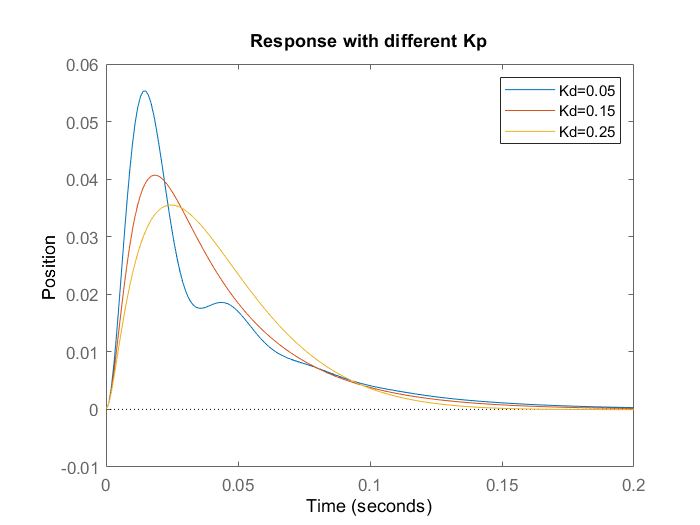

dist_cl=feedback(P_Motor,c);
t=0:0.001:0.2;
step(dist_cl(:,:,1),dist_cl(:,:,2),dist_cl(:,:,3),t)
ylabel('Position')
title('Response with different Kp')
legend('Kd=0.05','Kd=0.15','Kd=0.25')

At Kd=0.15 it reaches to zero quickly 

so selecting sys_cl =2 transfer function

Characteristics of step response

stepinfo(sys_cl(:,:,2))

ans = struct with fields:
        RiseTime: 0.0046
    SettlingTime: 0.0338
     SettlingMin: 0.9103
     SettlingMax: 1.1212
       Overshoot: 12.1175
      Undershoot: 0
            Peak: 1.1212
        PeakTime: 0.0122
